# 로봇 비전 HW1

due date : 10월 13일 23:59

코드 작성한 후 본인의 Github에 업로드하고 Repository URL을 적으세요. 

GitHub URL : https://github.com/dotoroi/Robotvision_HW1

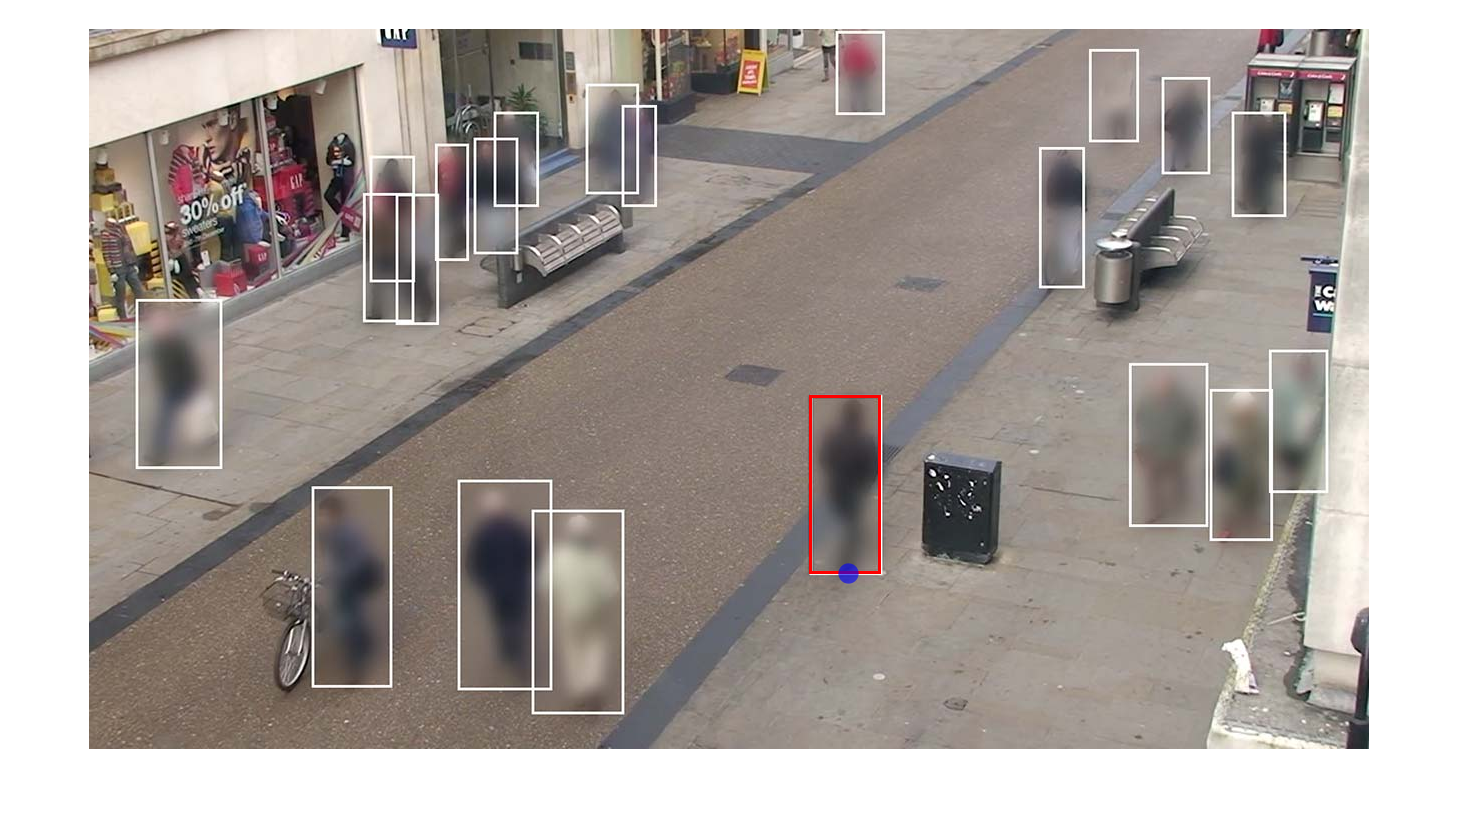

% image 정보 불러오기
img = imread("background.jpg");
img_rec = insertShape(img, 'Rectangle', [722 368 70 177], 'Color', "red", 'LineWidth', 3);      % 사각형 그리기
img_rec = insertShape(img_rec, 'FilledCircle', [760 545 10], 'Color', "blue", 'LineWidth', 10); 
figure(2);
imshow(img_rec);

- 임의의 카메라의 설치 위치와 각도에 따라 사람의 발(파란 점)의 3차원 좌표를 구하는 Matlab 코드를 작성하세요. 

- World Coordinate 원점에 대한 카메라의 위치는 다음과 같다.

- 카메라의 위치는 R과 t로 주어진다. 

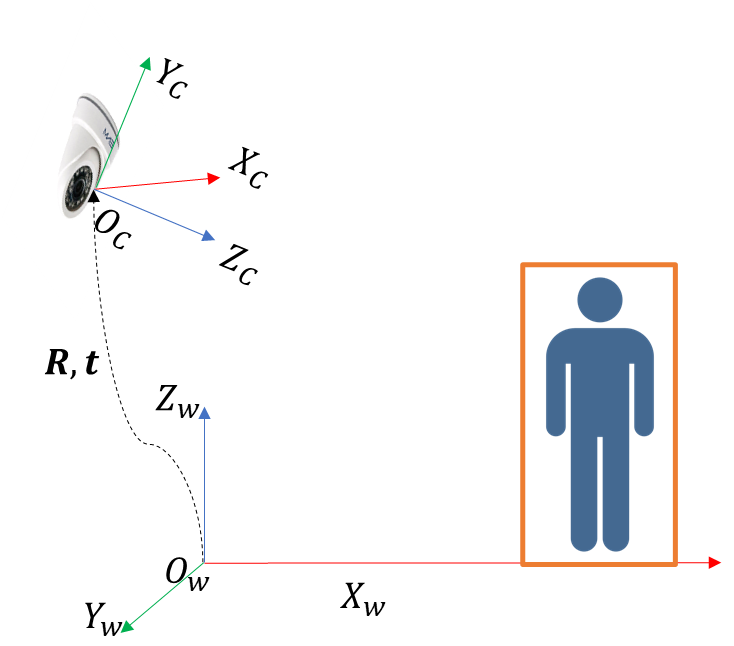

- f_x = 1000 pixel, f_y = 1000 pixel

- c_x = 640 pixel, c_y = 480 pixel

- 이미지 size : 1280*720

- 이미지 상 파란 점의 위치 : (760, 545)

% Intrinsic Parameters
fx = 1000;
fy = 1000;
cx = 640;
cy = 480;

% 파란점의 픽셀 위치
u = 760;
v = 545;

% 임의의 카메라 설치 위치
theta_x = pi/2 - pi/6;  % x축 각도
theta_y = -pi/2;        % y축 각도
theta_z = pi/2;         % z축 각도
% 위치
tx = 0;
ty = -5;
tz = 0.2;


% Camera Matrix?

K = [fx 0 cx ; 0 fy cy ; 0 0 1]

K =         1000           0         640
           0        1000         480
           0           0           1



% Rotation Matrix?

% cos(-+pi/2) = 0 

Rz = [ zeros -sin(theta_z) zeros; sin(theta_z) zeros zeros; zeros zeros 1 ];

Ry = [ zeros zeros sin(theta_y); zeros 1 zeros; -sin(theta_y) zeros zeros ];

Rx = [ 1 zeros zeros ; zeros cos(theta_x) -sin(theta_x); zeros sin(theta_x) cos(theta_x) ];

R = Rz * Ry * Rx

R =          0   -0.5000    0.8660
         0   -0.8660   -0.5000
    1.0000         0         0




% Translation Matrix?

t = [tx ; ty; tz ] - R*[0;0;0]

t =          0
   -5.0000
    0.2000




% World Coordinate 좌표 값?

% World Coordinate에서 Zw = 0
VIP = [ u; v; 1];

r1 = R(:,1);

r2 = R(:,2);

r3 = R(:,3);


C = [K.' * VIP, -r1, -r2];

D = linsolve(C, t)

D =     0.0000
    4.6486
   -9.8527



% s = 0 Xw = 4.6486 Yw = -9.8527 Zw = 0



